**Our last version suffered from lack of neighborhood, and some really big outliers in the LotArea**

format long g
%Add functions from shared folder
addpath('../Published')
filled_train = readtable('fillna_train.csv');

filled_train = filled_train(:,2:81)

filled_train = 1458×80 table
    Id    MSSubClass    MSZoning    LotFrontage    LotArea    Street    Alley     LotShape    LandContour    LotConfig    LandSlope    Neighborhood    Condition1    Condition2    BldgType    HouseStyle    OverallQual    OverallCond    YearBuilt    YearRemodAdd    RoofStyle    RoofMatl     Exterior1st    Exterior2nd    MasVnrType    MasVnrArea    ExterQual    ExterCond    Foundation    BsmtQual    BsmtCond    BsmtExposure   

%normalize the data

%I can't normalize non numeric fields!, so lets split it out

%[x mu sigma] = featureNormalize(filled_train)

[uniqueNeighborhoods,neighborhoodWeights,filled_train] = GenerateScalarValuesFromCategories(filled_train,'Neighborhood','NeighborhoodValue','GrLivArea','SalePrice');

oUniqueNames = 25×1 cell array
    {'Blmngtn'}
    {'Blueste'}
    {'BrDale' }
    {'BrkSide'}
    {'ClearCr'}
    {'CollgCr'}
    {'Crawfor'}
    {'Edwards'}
    {'Gilbert'}
    {'IDOTRR' }
    {'MeadowV'}
    {'Mitchel'}
    {'NAmes'  }
    {'NPkVill'}
    {'NWAmes' }
    {'NoRidge'}
    {'NridgHt'}
    {'OldTown'}
    {'SWISU'  }
    {'Sawyer' }
    {'SawyerW'}
    {'Somerst'}
    {'StoneBr'}
    {'Timber' }
    {'Veenker'}


len =     25


squareFootage =         1710      208500
        1262      181500
        1786      223500
        1717      140000
        2198      250000
        1362      143000
        1694      307000
        2090      200000
        1774      129900
        1077      118000


name = 'Blmngtn'

meanCostPrSqFt =           136.566973636099


name = 'Blueste'

meanCostPrSqFt =           98.9693692073101


name = 'BrDale'

meanCostPrSqFt =           91.9505433820985


name = 'BrkSide'

meanCostPrSqFt =            105.96680854866


name = 'ClearCr'

meanCostPrSqFt =           124.242988910295


name = 'CollgCr'

meanCostPrSqFt =           136.783679515791


name = 'Crawfor'

meanCostPrSqFt =           120.254826381373


name = 'Edwards'

meanCostPrSqFt =           103.218640955326


name = 'Gilbert'

meanCostPrSqFt =           119.114931256817


name = 'IDOTRR'

meanCostPrSqFt =           89.1360425104863


name = 'MeadowV'

meanCostPrSqFt =           101.926200571717


name = 'Mitchel'

meanCostPrSqFt =           126.017448636158


name = 'NAmes'

meanCostPrSqFt =            116.08938532777


name = 'NPkVill'

meanCostPrSqFt =           116.726891440128


name = 'NWAmes'

meanCostPrSqFt =           111.848349254388


name = 'NoRidge'

meanCostPrSqFt =           132.271687050705


name = 'NridgHt'

meanCostPrSqFt =           164.578057232102


name = 'OldTown'

meanCostPrSqFt =           91.4272819967726


name = 'SWISU'

meanCostPrSqFt =           84.7552333516497


name = 'Sawyer'

meanCostPrSqFt =           117.856162996609


name = 'SawyerW'

meanCostPrSqFt =           119.704424219655


name = 'Somerst'

meanCostPrSqFt =           141.335966424812


name = 'StoneBr'

meanCostPrSqFt =           165.402275322354


name = 'Timber'

meanCostPrSqFt =            139.76648322039


name = 'Veenker'

meanCostPrSqFt =           154.980913750757


len =     25


name = 'Blmngtn'

ans = 1×1 cell array
    {'Blmngtn'}


matchIndexes =    220
   230
   386
   444
   466
   559
   597
   639
   790
   851


name = 'Blueste'

ans = 1×1 cell array
    {'Blueste'}


matchIndexes =    599
   956


name = 'BrDale'

ans = 1×1 cell array
    {'BrDale'}


matchIndexes =    226
   228
   233
   236
   364
   431
   433
   501
   655
   837


name = 'BrkSide'

ans = 1×1 cell array
    {'BrkSide'}


matchIndexes =     10
    16
    30
    52
    78
   147
   150
   185
   251
   276


name = 'ClearCr'

ans = 1×1 cell array
    {'ClearCr'}


matchIndexes =     70
   121
   154
   167
   177
   250
   272
   280
   352
   359


name = 'CollgCr'

ans = 1×1 cell array
    {'CollgCr'}


matchIndexes =      1
     3
    14
    23
    33
    37
    44
    58
    60
    65


name = 'Crawfor'

ans = 1×1 cell array
    {'Crawfor'}


matchIndexes =      4
    93
   114
   115
   182
   191
   219
   252
   300
   301


name = 'Edwards'

ans = 1×1 cell array
    {'Edwards'}


matchIndexes =     40
    98
    99
   111
   118
   146
   156
   166
   176
   183


name = 'Gilbert'

ans = 1×1 cell array
    {'Gilbert'}


matchIndexes =     51
    73
    85
    87
    96
   112
   132
   148
   160
   169


name = 'IDOTRR'

ans = 1×1 cell array
    {'IDOTRR'}


matchIndexes =     22
    31
    53
    62
    89
   105
   109
   122
   126
   269


name = 'MeadowV'

ans = 1×1 cell array
    {'MeadowV'}


matchIndexes =     24
    76
   345
   358
   435
   490
   491
   614
   649
   915


name = 'Mitchel'

ans = 1×1 cell array
    {'Mitchel'}


matchIndexes =      6
    47
    72
    82
   138
   187
   202
   275
   277
   296


name = 'NAmes'

ans = 1×1 cell array
    {'NAmes'}


matchIndexes =     15
    17
    20
    27
    29
    34
    38
    39
    41
    45


name = 'NPkVill'

ans = 1×1 cell array
    {'NPkVill'}


matchIndexes =          127
         196
         505
         550
         675
         962
        1160
        1420
        1430


name = 'NWAmes'

ans = 1×1 cell array
    {'NWAmes'}


matchIndexes =      8
   101
   110
   125
   136
   153
   223
   246
   266
   294


name = 'NoRidge'

ans = 1×1 cell array
    {'NoRidge'}


matchIndexes =      5
    86
   227
   232
   273
   319
   360
   404
   424
   497


name = 'NridgHt'

ans = 1×1 cell array
    {'NridgHt'}


matchIndexes =     12
    21
    26
    28
    35
    36
    46
    63
    66
   152


name = 'OldTown'

ans = 1×1 cell array
    {'OldTown'}


matchIndexes =      9
    49
    64
    69
    75
    80
    94
   107
   108
   128


name = 'SWISU'

ans = 1×1 cell array
    {'SWISU'}


matchIndexes =    268
   292
   355
   381
   407
   462
   565
   576
   635
   681


name = 'Sawyer'

ans = 1×1 cell array
    {'Sawyer'}


matchIndexes =     11
    13
    18
    25
    32
    50
    79
   117
   135
   145


name = 'SawyerW'

ans = 1×1 cell array
    {'SawyerW'}


matchIndexes =     19
    43
    61
   102
   103
   119
   124
   149
   189
   209


name = 'Somerst'

ans = 1×1 cell array
    {'Somerst'}


matchIndexes =      7
    48
    57
    83
    88
   106
   116
   159
   181
   197


name = 'StoneBr'

ans = 1×1 cell array
    {'StoneBr'}


matchIndexes =     59
   173
   179
   190
   337
   379
   471
   475
   566
   595


name = 'Timber'

ans = 1×1 cell array
    {'Timber'}


matchIndexes =     42
   134
   158
   170
   175
   314
   336
   341
   430
   453


name = 'Veenker'

ans = 1×1 cell array
    {'Veenker'}


matchIndexes =            2
          54
         161
         327
         401
         672
         764
         849
        1155
        1164


**Since we did so poorly, we are going to add in neighborhood into the dataset and retest.**

**We use a generic function to turn a neighborhood into a numerical value**

% uniqueNeighborhoods = table2array(unique(filled_train(:,'Neighborhood')))
% neighborhoodWeights = zeros(length(uniqueNeighborhoods),1);
% %we group entries by neighborhood, and use the neighborhood price per square foot to set a multiplier in the neighborhood value
% %first get a simplified data set
% squareFootage = table2array([filled_train(:,'GrLivArea') filled_train(:,'SalePrice')])
% n = table2array(filled_train(:,'Neighborhood'));
% len = length(uniqueNeighborhoods)
% 
% %create a new value to store neighborhood value mean multiplier
% filled_train.NeighborhoodValue = zeros(length(n),1);
% for index = 1:len
%     %get the name fo the unique index
%     name = cell2mat(uniqueNeighborhoods(index))
%     % find matching indexes in neighborhood list
%     matchIndexes = find(strcmp(n,name));
%     
%     %get houses that match
%     houses = squareFootage(matchIndexes,:);
%     %calculate dollar per square foot of each
%     dollarPrSqFt = houses(:,2)./(houses(:,1));
%     meanCostPrSqFt = mean(dollarPrSqFt)
%     %replace the neighborhood value in the weighting array
%     neighborhoodWeights(index) = meanCostPrSqFt;    
% end
% %create a new table row for neighborhood mean multiplier

**I feel like this would probably go a lot smoother in python (...trying to get cell/table/matrix/vectors to play together is a PITA) - But I now have weighting factors based on how expensive or cheap a neighborhood is.**

**This needs to get fed back into the filled_train in a repeatable way (since im going to do the same thing to the test data)**

**Here, we  add the weights into the right values in the training data. I'm being lazy at this point!**

% len = length(uniqueNeighborhoods)
% for index = 1:len
%     %get the name fo the unique index
%     name = cell2mat(uniqueNeighborhoods(index))
%     % find matching indexes in neighborhood list
%     uniqueNeighborhoods(index)
%     n = table2array(filled_train(:,'Neighborhood'));
%     matchIndexes = find(strcmp(n,name))
%      %get houses that match
%     filled_train(matchIndexes,'NeighborhoodValue') = {neighborhoodWeights(index)};
% end

%check some arbitrary values for matches
[filled_train(599,1) {neighborhoodWeights(2)}]

ans = 1×2 table
    NeighborhoodValue          Var2      
    _________________    ________________

    98.9693692073101     98.9693692073101


[filled_train(2,1) {neighborhoodWeights(25)}]

ans = 1×2 table
    NeighborhoodValue          Var2      
    _________________    ________________

    154.980913750757     154.980913750757


**This seems to test out from spot inspection. **

**We want to use the following fields for our comparison:**

LotArea, Neighborhood, OverallCond,YearBuilt, ExterQual,CentralAir,GrLivArea,BedroomAbvGr,HalfBath,FullBath, (aha, I thought saleprice belonged here and was amazed at how accurate my model was.. oi!)

Of these, Neighborhood,CentralAir,ExterQual are text *(we'll try to assign numeric values to these later)*

***We cheat a little and look at this graph elsewhere to notice that OverallQual has strong relationship to sale Price, and add this.***

***Looking at this graph, I cut OverallCond from my model for right now.***

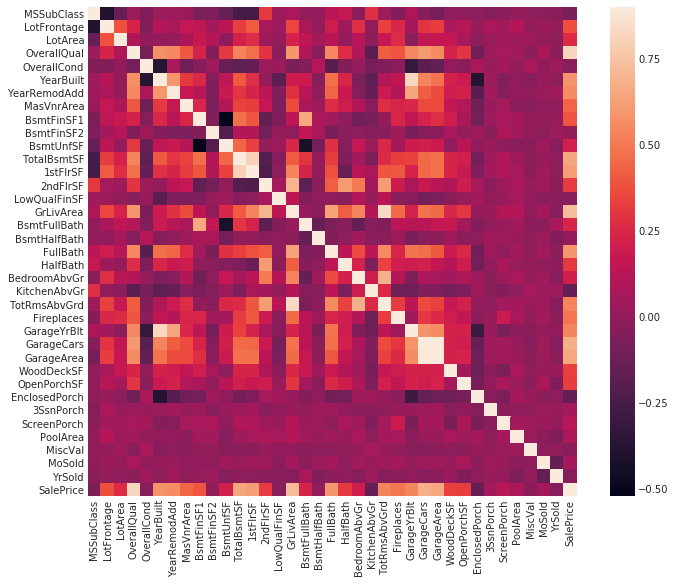

numericFields = ["LotArea",'YearBuilt','GrLivArea','BedroomAbvGr','FullBath','OverallQual','NeighborhoodValue'] %new field at end

numericFields = 1×7 string array
    "LotArea"    "YearBuilt"    "GrLivArea"    "BedroomAbvGr"    "FullBath"    "OverallQual"    "NeighborhoodValue"


foo = [1 2 3]

foo =      1     2     3


%get prices vector for later
prices = table2array(filled_train(:,'SalePrice'))

prices =       208500
      181500
      223500
      140000
      250000
      143000
      307000
      200000
      129900
      118000



textFields = ["CentralAir","ExterQual"]

textFields = 1×2 string array
    "CentralAir"    "ExterQual"


numeric_data = fillTable(filled_train,numericFields)

sz =         1458          80


sz =         1458           7


numeric_data =                       8450                      2003                      1710                         3                         2                         7          136.783679515791
                      9600                      1976                      1262                         3                         2                         6          154.980913750757
                     11250                      2001                      1786                         3                         2                         7          136.783679515791
                      9550                      1915                      1717                         3                         1                         7          120.254826381373
                     14260                      2000                      2198                         4                         2                         8          132.271687050705
                     14115                      1993                  

%uses dynamic table size slower but works with text
text_data = fillTableSlow(filled_train,textFields)

text_data = 1458×2 cell array
    {'Y'}    {'Gd'}
    {'Y'}    {'TA'}
    {'Y'}    {'Gd'}
    {'Y'}    {'TA'}
    {'Y'}    {'Gd'}
    {'Y'}    {'TA'}
    {'Y'}    {'Gd'}
    {'Y'}    {'TA'}
    {'Y'}    {'TA'}
    {'Y'}    {'TA'}
    {'Y'}    {'TA'}
    {'Y'}    {'Ex'}
    {'Y'}    {'TA'}
    {'Y'}    {'Gd'}
    {'Y'}    {'TA'}
    {'Y'}    {'TA'}
    {'Y'}    {'TA'}
    {'Y'}    {'TA'}
    {'Y'}    {'TA'}
    {'Y'}    {'TA'}
    {'Y'}    {'Gd'}
    {'Y'}    {'TA'}
    {'Y'}    {'Gd'}
    {'Y'}    {'TA'}
    {'Y'}    {'TA'}
    {'Y'}    {'Gd'}
    {'Y'}    {'TA'}
    {'Y'}    {'Gd'}
    {'Y'}    {'TA'}
    {'N'}    {'TA'}
    {'N'}    {'TA'}
    {'Y'}    {'TA'}
    {'Y'}    {'Gd'}
    {'Y'}    {'TA'}
    {'Y'}    {'Ex'}
    {'Y'}    {'Gd'}
    {'Y'}    {'TA'}
    {'Y'}    {'TA'}
    {'Y'}    {'TA'}
    {'N'}    {'TA'}
    {'Y'}    {'TA'}
    {'Y'}    {'TA'}
    {'Y'}    {'TA'}
    {'Y'}    {'TA'}
    {'Y'}    {'TA'}
    {'Y'}    {'Ex'}
    {'Y'}    {'Gd'}
    {'Y'}    {'Gd'}
    {'Y'} 

**Let's look at the plot pre-normalization**

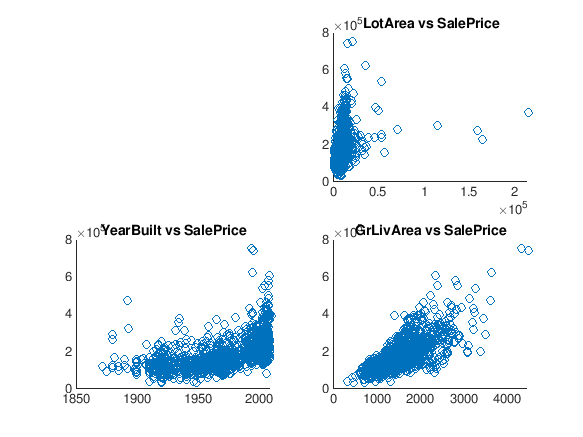

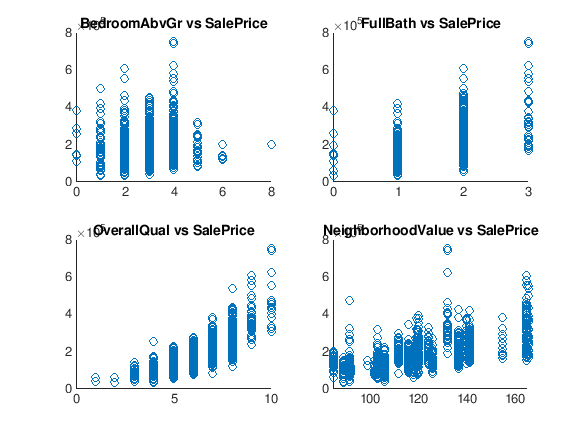

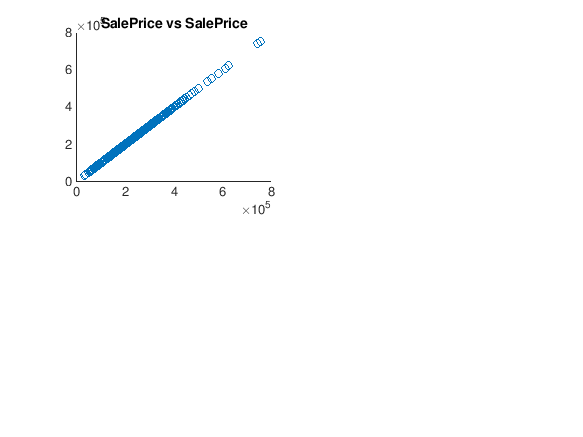

xField = 'LotArea';
yField = 'SalePrice';

index = 1;
graphFields = [numericFields  "SalePrice"];
graphData = [numeric_data prices];
for gf = graphFields
    sp = [2 2 mod(index,4)+1];
    %title('Sp')
    graphIt(graphData,index,gf,length(graphFields),graphFields(length(graphFields)),sp);
    index = index +1;
    if mod(index,4) == 0
        figure
    end
    
end

**Before normalizing, let's get rid of the extreme outliers in lot area and bedroomabovegr (what is that lone 8 doing out there?)**

%Cut LotArea > 10000
%Cut 8 bedrooms
trash = isoutlier(numeric_data(:,1)) %lot area

trash = 1458×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


indexes = find(trash>0)

indexes =     54
    67
   114
   121
   160
   172
   186
   198
   250
   261


numeric_data(indexes,:) = []

numeric_data =                       8450                      2003                      1710                         3                         2                         7          136.783679515791
                      9600                      1976                      1262                         3                         2                         6          154.980913750757
                     11250                      2001                      1786                         3                         2                         7          136.783679515791
                      9550                      1915                      1717                         3                         1                         7          120.254826381373
                     14260                      2000                      2198                         4                         2                         8          132.271687050705
                     14115                      1993                  

%remember to delete from prices too!
prices(indexes,:) = []

prices =       208500
      181500
      223500
      140000
      250000
      143000
      307000
      200000
      129900
      118000


**And Re-Graph output**

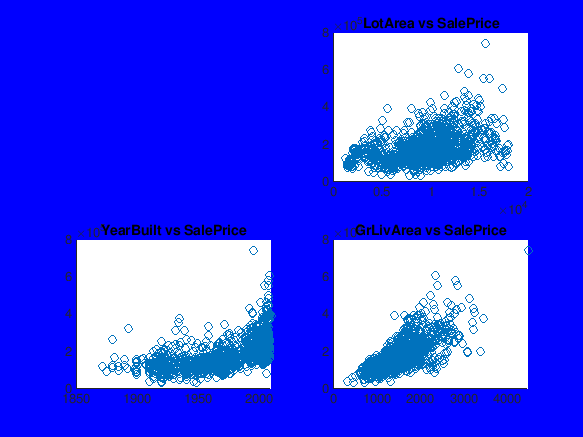

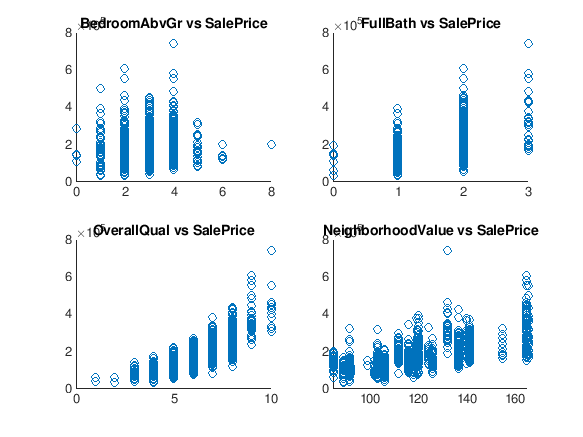

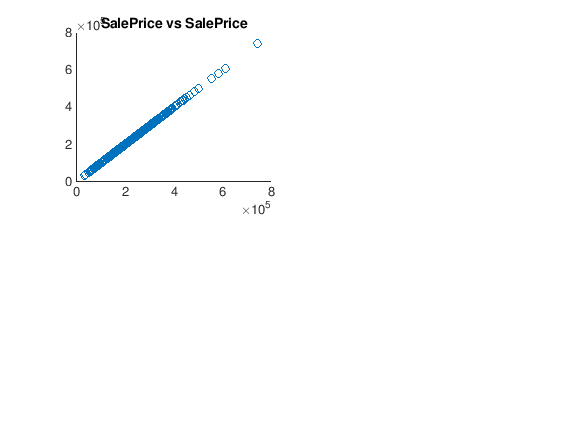


index = 1;
graphFields = [numericFields  "SalePrice"];
graphData = [numeric_data prices];
figure ('Color','Blue')
for gf = graphFields
    sp = [2 2 mod(index,4)+1];
    %title('Sp')
    graphIt(graphData,index,gf,length(graphFields),graphFields(length(graphFields)),sp);
    index = index +1;
    if mod(index,4) == 0
        figure
    end
    
end

**Now, normalize the numeric data, ignoring text fields for now. (more on this later!)**

[normalized_numeric_data mu sigma] = featureNormalize(numeric_data);


**Let's see if our graphs improved...**

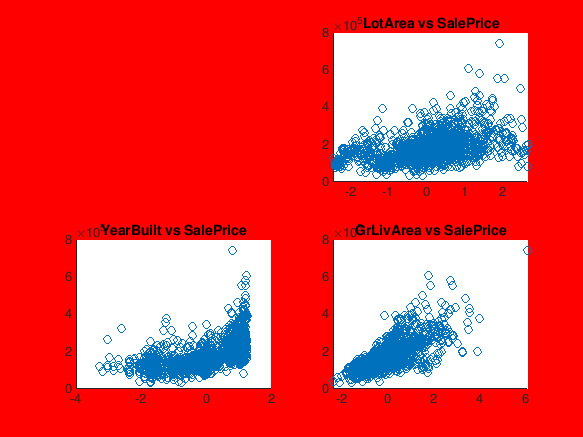

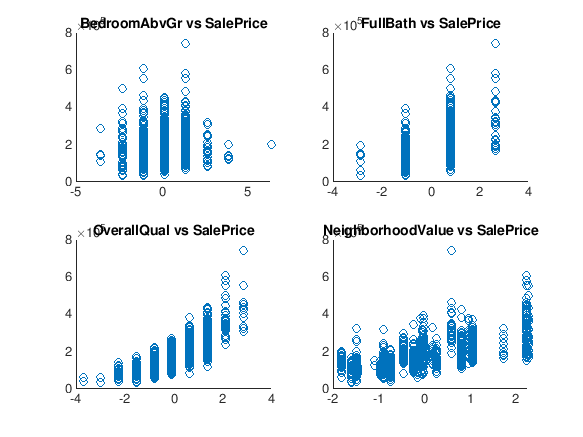

xField = 'LotArea';
yField = 'SalePrice';

index = 1;
graphFields = [numericFields  "SalePrice"];
graphData = [normalized_numeric_data prices];

figure ('Color','Red')
for gf = graphFields
    sp = [2 2 mod(index,4)+1];
    %title('Sp')
    graphIt(graphData,index,gf,length(graphFields),graphFields(length(graphFields)),sp);
    index = index +1;
    if mod(index,4) == 0
        figure
    end
    
end


%onePad the data for \theta 0

normalized_numeric_data = onePad(normalized_numeric_data)

normalized_numeric_data =                          1        -0.259603853550894          1.04132368273415          0.45226335423717         0.177510719424401         0.818810691103354         0.666418162013642         0.824339551330109
                         1        0.0948909070251884         0.148922644512257        -0.466764025746531         0.177510719424401         0.818810691103354        -0.062004504518861          1.74913823851576
                         1          0.60351382437348         0.975219902125124         0.608169784770119         0.177510719424401         0.818810691103354         0.666418162013642         0.824339551330109
                         1        0.0794780913479674         -1.86724266406314         0.466623157049415         0.177510719424401         -1.02450226568004         0.666418162013642       -0.0156706107648439
                         1          1.53136532814218         0.942168011820609          1.45334675029084          1.41831064820096        

**Perform gradient descent based on numeric values**


sz = size(normalized_numeric_data);
theta = zeros(sz(2),1);
alpha = 0.01;
iter = 20000;
[theta,jh] = gradientDescent(normalized_numeric_data,prices,theta,alpha,iter);

theta

theta =           177962.005007151
           11211.298688224
          7432.27204848429
           37118.376079579
         -11018.7240757281
         -3004.72893645069
          25034.4064674332
          15943.7005065146


jh(iter-50:iter,:)

ans =           487510564.989114
          487510564.989114
          487510564.989114
          487510564.989114
          487510564.989114
          487510564.989114
          487510564.989114
          487510564.989114
          487510564.989114
          487510564.989114


%plot(jh)

**Our addition of neighborhood value has increased accuracy from ~700m on J to ~487M, significant?**

**Now, calculate prices **

predictions = normalized_numeric_data*theta

predictions =           224988.351086931
           184726.41070432
          239960.713418055
          199851.441585037
          282396.734519903
          203299.366992383
          251586.936203041
          233026.296552104
          181043.394128884
          115276.888712582


prices

prices =       208500
      181500
      223500
      140000
      250000
      143000
      307000
      200000
      129900
      118000


%random samples...
guesses = [predictions prices]

guesses =           224988.351086931                    208500
           184726.41070432                    181500
          239960.713418055                    223500
          199851.441585037                    140000
          282396.734519903                    250000
          203299.366992383                    143000
          251586.936203041                    307000
          233026.296552104                    200000
          181043.394128884                    129900
          115276.888712582                    118000



%so far so good, right? This looks like it estimates a little high...

**So far so good, now to apply to test data!**

filled_test = readtable('test_fillna.csv');

filled_test = filled_test(:,2:80);
%extract id and remove from our dataset
test_ids = filled_test(:,1)

test_ids = 1459×1 table
     Id 
    ____

    1461
    1462
    1463
    1464
    1465
    1466
    1467
    1468
    1469
    1470
    1471
    1472
    1473
    1474
    1475
    1476


filled_test = filled_test(:,2:79)

filled_test = 1459×78 table
    MSSubClass    MSZoning    LotFrontage    LotArea    Street    Alley     LotShape    LandContour    LotConfig    LandSlope    Neighborhood    Condition1    Condition2    BldgType    HouseStyle    OverallQual    OverallCond    YearBuilt    YearRemodAdd    RoofStyle    RoofMatl     Exterior1st    Exterior2nd    MasVnrType    MasVnrArea    ExterQual    ExterCond    Foundation    BsmtQual    BsmtCond    BsmtExposure    BsmtFinType1

**Add neighborhood weights to test data**

format long g
filled_test = AddWeightsToTable(filled_test,uniqueNeighborhoods,neighborhoodWeights, 'Neighborhood','NeighborhoodValue');

len =     25


name = 'Blmngtn'

ans = 1×1 cell array
    {'Blmngtn'}


matchIndexes =           24
         226
         525
         526
         527
         861
         862
        1212
        1213
        1214


name = 'Blueste'

ans = 1×1 cell array
    {'Blueste'}


matchIndexes =          139
         140
         448
         449
         450
         750
        1110
        1112


name = 'BrDale'

ans = 1×1 cell array
    {'BrDale'}


matchIndexes =           12
          13
         192
         193
         502
         503
         504
         823
         824
        1183


name = 'BrkSide'

ans = 1×1 cell array
    {'BrkSide'}


matchIndexes =     82
    83
    84
    85
    86
    87
    88
    89
    90
   364


name = 'ClearCr'

ans = 1×1 cell array
    {'ClearCr'}


matchIndexes =           95
          96
         106
         108
         387
         413
         687
         690
         705
        1032


name = 'CollgCr'

ans = 1×1 cell array
    {'CollgCr'}


matchIndexes =    117
   119
   120
   121
   122
   123
   124
   125
   405
   406


name = 'Crawfor'

ans = 1×1 cell array
    {'Crawfor'}


matchIndexes =    136
   137
   138
   144
   439
   440
   441
   442
   443
   444


name = 'Edwards'

ans = 1×1 cell array
    {'Edwards'}


matchIndexes =    109
   110
   111
   112
   113
   114
   126
   127
   128
   129


name = 'Gilbert'

ans = 1×1 cell array
    {'Gilbert'}


matchIndexes =      3
     4
     6
     7
     8
     9
    23
    25
    26
   167


name = 'IDOTRR'

ans = 1×1 cell array
    {'IDOTRR'}


matchIndexes =    141
   142
   143
   363
   373
   376
   377
   378
   453
   454


name = 'MeadowV'

ans = 1×1 cell array
    {'MeadowV'}


matchIndexes =          154
         155
         156
         157
         782
         783
         784
         785
         787
        1142


name = 'Mitchel'

ans = 1×1 cell array
    {'Mitchel'}


matchIndexes =    145
   146
   147
   151
   152
   153
   158
   159
   160
   161


name = 'NAmes'

ans = 1×1 cell array
    {'NAmes'}


matchIndexes =      1
     2
    10
    11
    50
    51
    52
    53
    54
    55


name = 'NPkVill'

ans = 1×1 cell array
    {'NPkVill'}


matchIndexes =     14
    15
   194
   195
   196
   197
   198
   199
   505
   506


name = 'NWAmes'

ans = 1×1 cell array
    {'NWAmes'}


matchIndexes =     46
    47
    48
    49
   178
   179
   180
   181
   185
   186


name = 'NoRidge'

ans = 1×1 cell array
    {'NoRidge'}


matchIndexes =     27
    34
    35
   238
   239
   240
   241
   278
   536
   537


name = 'NridgHt'

ans = 1×1 cell array
    {'NridgHt'}


matchIndexes =     16
    17
    18
    19
    20
    21
    22
   201
   202
   203


name = 'OldTown'

ans = 1×1 cell array
    {'OldTown'}


matchIndexes =     71
    72
    73
    74
    75
    76
    77
    78
    79
    80


name = 'SWISU'

ans = 1×1 cell array
    {'SWISU'}


matchIndexes =     97
    98
    99
   100
   132
   133
   134
   135
   437
   438


name = 'Sawyer'

ans = 1×1 cell array
    {'Sawyer'}


matchIndexes =     33
   101
   102
   103
   104
   105
   107
   271
   272
   273


name = 'SawyerW'

ans = 1×1 cell array
    {'SawyerW'}


matchIndexes =     31
    32
   115
   116
   118
   256
   257
   258
   259
   260


name = 'Somerst'

ans = 1×1 cell array
    {'Somerst'}


matchIndexes =     28
    29
    30
    36
    37
    38
    39
    40
    41
    42


name = 'StoneBr'

ans = 1×1 cell array
    {'StoneBr'}


matchIndexes =      5
   170
   171
   172
   479
   480
   483
   484
   485
   487


name = 'Timber'

ans = 1×1 cell array
    {'Timber'}


matchIndexes =    148
   149
   150
   461
   462
   463
   464
   465
   466
   767


name = 'Veenker'

ans = 1×1 cell array
    {'Veenker'}


matchIndexes =    277
   284
   285
   286
   562
   579
   580
   581
   902
   915


% n = table2array(filled_test(:,'Neighborhood'));
% filled_test.NeighborhoodValue = zeros(length(n),1);
% len = length(uniqueNeighborhoods)
% for index = 1:len
%     %get the name fo the unique index
%     name = cell2mat(uniqueNeighborhoods(index))
%     % find matching indexes in neighborhood list
%     uniqueNeighborhoods(index)
%     matchIndexes = find(strcmp(n,name))
%      %get houses that match
%     filled_test(matchIndexes,'NeighborhoodValue') = {neighborhoodWeights(index)};
% end
% 
% filled_test


%add in the

%numericFields = ["LotArea",'OverallCond','YearBuilt','GrLivArea','BedroomAbvGr','FullBath']
%textFields = ["Neighborhood","CentralAir","ExterQual"]
%get prices vector for later
%prices = table2array(filled_train(:,'SalePrice'))


test_numeric_data = fillTable(filled_test,numericFields)

sz =         1459          79


sz =         1459           7


test_numeric_data =                      11622                      1961                       896                         2                         1                         5           116.08938532777
                     14267                      1958                      1329                         3                         1                         6           116.08938532777
                     13830                      1997                      1629                         3                         2                         5          119.114931256817
                      9978                      1998                      1604                         3                         2                         6          119.114931256817
                      5005                      1992                      1280                         2                         2                         8          165.402275322354
                     10000                      1993             

%uses dynamic table size slower but works with text
test_text_data = fillTableSlow(filled_test,textFields)

test_text_data = 1459×2 cell array
    {'Y'}    {'TA'}
    {'Y'}    {'TA'}
    {'Y'}    {'TA'}
    {'Y'}    {'TA'}
    {'Y'}    {'Gd'}
    {'Y'}    {'TA'}
    {'Y'}    {'TA'}
    {'Y'}    {'TA'}
    {'Y'}    {'TA'}
    {'Y'}    {'TA'}
    {'Y'}    {'Gd'}
    {'Y'}    {'TA'}
    {'Y'}    {'TA'}
    {'Y'}    {'TA'}
    {'Y'}    {'TA'}
    {'Y'}    {'Ex'}
    {'Y'}    {'Gd'}
    {'Y'}    {'Gd'}
    {'Y'}    {'Gd'}
    {'Y'}    {'Ex'}
    {'Y'}    {'Gd'}
    {'Y'}    {'Gd'}
    {'Y'}    {'Gd'}
    {'Y'}    {'Gd'}
    {'Y'}    {'Gd'}
    {'Y'}    {'Gd'}
    {'Y'}    {'Gd'}
    {'Y'}    {'Gd'}
    {'Y'}    {'Gd'}
    {'Y'}    {'Gd'}
    {'Y'}    {'Gd'}
    {'N'}    {'TA'}
    {'Y'}    {'TA'}
    {'Y'}    {'Gd'}
    {'Y'}    {'Gd'}
    {'Y'}    {'Gd'}
    {'Y'}    {'Gd'}
    {'Y'}    {'Gd'}
    {'Y'}    {'Gd'}
    {'Y'}    {'Gd'}
    {'Y'}    {'Gd'}
    {'Y'}    {'Gd'}
    {'Y'}    {'Gd'}
    {'Y'}    {'Gd'}
    {'Y'}    {'Gd'}
    {'Y'}    {'TA'}
    {'Y'}    {'TA'}
    {'Y'}    {'TA'}
    {

%now, renormalize the data
normalized_test_data = reNormalize(test_numeric_data,mu,sigma);

XNorm =          0.718185173012004        -0.346855710055463         -1.21757657278679         -1.06328920935216         -1.02450226568004        -0.790427171051364        -0.227361814393954
          1.53352312233699        -0.446011380969007        -0.329320198829326         0.177510719424401         -1.02450226568004        -0.062004504518861        -0.227361814393954
          1.39881511331808         0.843012340907065         0.286099921695474         0.177510719424401         0.818810691103354        -0.790427171051364       -0.0736010358561939
         0.211411793544979          0.87606423121158         0.234814911651741         0.177510719424401         0.818810691103354        -0.062004504518861       -0.0736010358561939
         -1.32154685371142         0.677752889384492        -0.429838818515043         -1.06328920935216         0.818810691103354          1.39484082854615          2.27876056329633
         0.218193432442956         0.710804779689006         0.33943633214095

normalized_test_data = onePad(normalized_test_data)

normalized_test_data =                          1         0.718185173012004        -0.346855710055463         -1.21757657278679         -1.06328920935216         -1.02450226568004        -0.790427171051364        -0.227361814393954
                         1          1.53352312233699        -0.446011380969007        -0.329320198829326         0.177510719424401         -1.02450226568004        -0.062004504518861        -0.227361814393954
                         1          1.39881511331808         0.843012340907065         0.286099921695474         0.177510719424401         0.818810691103354        -0.790427171051364       -0.0736010358561939
                         1         0.211411793544979          0.87606423121158         0.234814911651741         0.177510719424401         0.818810691103354        -0.062004504518861       -0.0736010358561939
                         1         -1.32154685371142         0.677752889384492        -0.429838818515043         -1.06328920935216         0.


%now calculate dem prices
test_prices = normalized_test_data * theta

test_prices =           129622.980617536
          175561.257187213
          185152.006829325
          188417.337012438
          232734.747875984
          191148.492021118
          148286.118151527
          172386.647560374
            204556.6842736
          101397.099634133


**Now, write to CSV and submit for score**

format long
test_results = [table2array(test_ids)  test_prices]

test_results = 	1.0e+05 *

   0.014610000000000   1.296229806175359
   0.014620000000000   1.755612571872134
   0.014630000000000   1.851520068293252
   0.014640000000000   1.884173370124380
   0.014650000000000   2.327347478759843
   0.014660000000000   1.911484920211183
   0.014670000000000   1.482861181515266
   0.014680000000000   1.723866475603741
   0.014690000000000   2.045566842735995
   0.014700000000000   1.013970996341327




%unfortunately dlmw write forces scientific notation, so lets do it ourselves
 fid = fopen('results-fp-tk3.csv', 'w') ;
 fprintf(fid,"Id,SalePrice\n")

ans =     13


     for  index =  1:length(test_results)
         fprintf(fid, '%i,', test_results(index,1));
         fprintf(fid, '%0.9f\n', test_results(index,2));
     end
 fclose(fid) ;

**This version scored 0.200 which is a reasonably significant jump. This is close to my highest matlab-assisted (app) value. I now have a reasonably decent set of funcs to work with too!**